clear all
clear ZoneTime
BefTime=6*1e4;
tps=[0:0.01:BefTime*2/1e4];
StepBackFromStart=0.5*1e4;

SessTypes={'Habituation24HPre','Habituation','TestPre','TestPost','UMazeCond','UMazeCondBlockedShock','UMazeCondBlockedSafe','Extinction'};
for ss=1:length(SessTypes)
    Files=PathForExperimentsEmbReact([SessTypes{ss},'_EyeShock']);
    MouseToAvoid=[560]; % mice with noisy data to exclude
    Files=RemoveElementsFromDir(Files,'nmouse',MouseToAvoid);
    
    for mm=1:length(Files.path)
        RiskAsess.(SessTypes{ss}).ToSafeMov{mm}=[];RiskAsess.(SessTypes{ss}).ToSafeType{mm}=[];RiskAsess.(SessTypes{ss}).ToSafePos{mm}=[];
        RiskAsess.(SessTypes{ss}).ToShockMov{mm}=[];RiskAsess.(SessTypes{ss}).ToShockType{mm}=[];RiskAsess.(SessTypes{ss}).ToShockPos{mm}=[];
        for c=1:length(Files.path{mm})
            cd(Files.path{mm}{c})
            clear Behav
            load('behavResources_SB.mat')
            for type=1:3
                RiskAsess.(SessTypes{ss}).ToSafeNumEv{type}(mm,c)=sum(Behav.RAUser.ToSafe>=type-1);
                RiskAsess.(SessTypes{ss}).ToShockNumEv{type}(mm,c)=sum(Behav.RAUser.ToShock>=type-1);
            end
            
            % Shock
            if not(isempty(Start(Behav.RAEpoch.ToShock)))
                SmooDiffLinDist=tsd(Range(Behav.LinearDist),[0;diff(runmean(Data(Behav.LinearDist),20))]);
                tpsout=FindClosestZeroCross(Start(Behav.RAEpoch.ToShock)-StepBackFromStart,SmooDiffLinDist,1);
                for t=1:length(tpsout)
                    try
                        LitEp=intervalSet(tpsout(t)-BefTime,tpsout(t)+BefTime);
                        dattemp=interp1(Range(Restrict(SmooDiffLinDist,LitEp))-Start(LitEp),Data(Restrict(Behav.Vtsd,LitEp)),tps*1e4);
                        RiskAsess.(SessTypes{ss}).ToShockMov{mm}=[RiskAsess.(SessTypes{ss}).ToShockMov{mm};dattemp];
                        dattemp=interp1(Range(Restrict(SmooDiffLinDist,LitEp))-Start(LitEp),Data(Restrict(Behav.LinearDist,LitEp)),tps*1e4);
                        RiskAsess.(SessTypes{ss}).ToShockPos{mm}=[RiskAsess.(SessTypes{ss}).ToShockPos{mm};dattemp];
                        RiskAsess.(SessTypes{ss}).ToShockType{mm}=[RiskAsess.(SessTypes{ss}).ToShockType{mm},Behav.RAUser.ToShock(t)];
                    end
                end
            end
            
            % Safe
            if not(isempty(Start(Behav.RAEpoch.ToSafe)))
                SmooDiffLinDist=tsd(Range(Behav.LinearDist),[0;diff(runmean(Data(Behav.LinearDist),20))]);
                tpsout=FindClosestZeroCross(Start(Behav.RAEpoch.ToSafe)-StepBackFromStart,SmooDiffLinDist,-1);
                for t=1:length(tpsout)
                    try
                        LitEp=intervalSet(tpsout(t)-BefTime,tpsout(t)+BefTime);
                        dattemp=interp1(Range(Restrict(SmooDiffLinDist,LitEp))-Start(LitEp),Data(Restrict(Behav.Vtsd,LitEp)),tps*1e4);
                        RiskAsess.(SessTypes{ss}).ToSafeMov{mm}=[ RiskAsess.(SessTypes{ss}).ToSafeMov{mm};dattemp];
                        dattemp=interp1(Range(Restrict(SmooDiffLinDist,LitEp))-Start(LitEp),Data(Restrict(Behav.LinearDist,LitEp)),tps*1e4);
                        RiskAsess.(SessTypes{ss}).ToSafePos{mm}=[RiskAsess.(SessTypes{ss}).ToSafePos{mm};dattemp];
                        RiskAsess.(SessTypes{ss}).ToSafeType{mm}=[RiskAsess.(SessTypes{ss}).ToSafeType{mm},Behav.RAUser.ToSafe(t)];
                    end
                end
            end
        end
    end
end
for type=1:3
    RiskAsess.Habituation.ToShockNumEv{type}=RiskAsess.Habituation.ToShockNumEv{type}+RiskAsess.Habituation24HPre.ToShockNumEv{type};
    RiskAsess.Habituation.ToSafeNumEv{type}=RiskAsess.Habituation.ToSafeNumEv{type}+RiskAsess.Habituation24HPre.ToSafeNumEv{type};
end


for ss=1:length(SessTypes)
    AllEventsMov.(SessTypes{ss}).ToSafe=[];AllEventsMov.(SessTypes{ss}).ToShock=[];
    AllEventsPos.(SessTypes{ss}).ToSafe=[];AllEventsPos.(SessTypes{ss}).ToShock=[];
    AllEventsID.(SessTypes{ss}).ToSafe=[];AllEventsID.(SessTypes{ss}).ToShock=[];
    
    for mm=1:size(RiskAsess.(SessTypes{ss}).ToSafeMov,2)
        AllEventsMov.(SessTypes{ss}).ToSafe=[AllEventsMov.(SessTypes{ss}).ToSafe;RiskAsess.(SessTypes{ss}).ToSafeMov{mm}];
        AllEventsMov.(SessTypes{ss}).ToShock=[AllEventsMov.(SessTypes{ss}).ToShock;RiskAsess.(SessTypes{ss}).ToShockMov{mm}];
        
        AllEventsPos.(SessTypes{ss}).ToSafe=[AllEventsPos.(SessTypes{ss}).ToSafe;RiskAsess.(SessTypes{ss}).ToSafePos{mm}];
        AllEventsPos.(SessTypes{ss}).ToShock=[AllEventsPos.(SessTypes{ss}).ToShock;RiskAsess.(SessTypes{ss}).ToShockPos{mm}];
        
        AllEventsID.(SessTypes{ss}).ToSafe=[AllEventsID.(SessTypes{ss}).ToSafe,RiskAsess.(SessTypes{ss}).ToSafeType{mm}];
        AllEventsID.(SessTypes{ss}).ToShock=[AllEventsID.(SessTypes{ss}).ToShock,RiskAsess.(SessTypes{ss}).ToShockType{mm}];
    end
end

AllEventsMov.Habituation.ToSafe=[AllEventsMov.Habituation.ToSafe;AllEventsMov.Habituation24HPre.ToSafe];
AllEventsMov.Habituation.ToShock=[AllEventsMov.Habituation.ToShock;AllEventsMov.Habituation24HPre.ToShock];
AllEventsPos.Habituation.ToSafe=[AllEventsPos.Habituation.ToSafe;AllEventsPos.Habituation24HPre.ToSafe];
AllEventsPos.Habituation.ToShock=[AllEventsPos.Habituation.ToShock;AllEventsPos.Habituation24HPre.ToShock];
AllEventsID.Habituation.ToSafe=[AllEventsID.Habituation.ToSafe,AllEventsID.Habituation24HPre.ToSafe];
AllEventsID.Habituation.ToShock=[AllEventsID.Habituation.ToShock,AllEventsID.Habituation24HPre.ToShock];



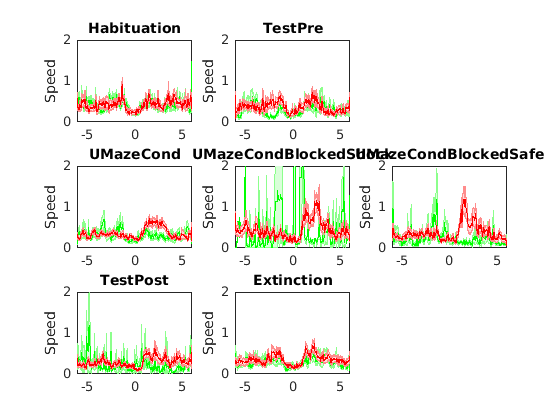


SessTypes={'Habituation','TestPre','UMazeCond','UMazeCondBlockedShock','UMazeCondBlockedSafe','TestPost','Extinction'};
SessNum=[1,2,4,5,6,7,8];
Lim=-1;
figure
for ss=1:length(SessTypes)
    subplot(3,3,SessNum(ss))
    shadedErrorBar(tps-BefTime/1e4,nanmean((AllEventsMov.(SessTypes{ss}).ToSafe(AllEventsID.(SessTypes{ss}).ToSafe>Lim,:)')'),stdError((AllEventsMov.(SessTypes{ss}).ToSafe(AllEventsID.(SessTypes{ss}).ToSafe>Lim,:)')'),'g');hold on
    shadedErrorBar(tps-BefTime/1e4,nanmean((AllEventsMov.(SessTypes{ss}).ToShock(AllEventsID.(SessTypes{ss}).ToShock>Lim,:)')'),stdError((AllEventsMov.(SessTypes{ss}).ToShock(AllEventsID.(SessTypes{ss}).ToShock>Lim,:)')'),'r'); hold on
    title(SessTypes{ss})
    ylabel('Speed')
    ylim([0 2])
    xlim([-BefTime/1e4 BefTime/1e4])
end

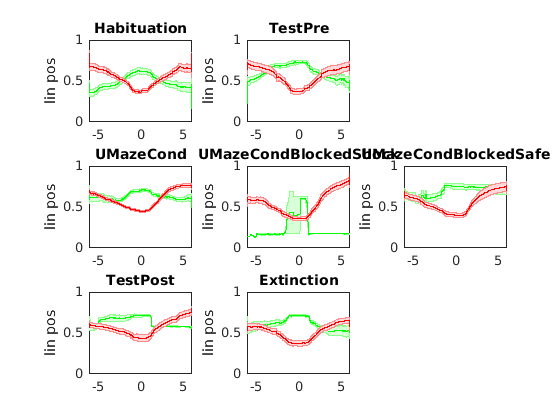


Lim=-1;
figure
for ss=1:length(SessTypes)
    subplot(3,3,SessNum(ss))
    shadedErrorBar(tps-BefTime/1e4,nanmean((AllEventsPos.(SessTypes{ss}).ToSafe(AllEventsID.(SessTypes{ss}).ToSafe>Lim,:)')'),stdError((AllEventsPos.(SessTypes{ss}).ToSafe(AllEventsID.(SessTypes{ss}).ToSafe>Lim,:)')'),'g'); hold on
    shadedErrorBar(tps-BefTime/1e4,nanmean((AllEventsPos.(SessTypes{ss}).ToShock(AllEventsID.(SessTypes{ss}).ToShock>Lim,:)')'),stdError((AllEventsPos.(SessTypes{ss}).ToShock(AllEventsID.(SessTypes{ss}).ToShock>Lim,:)')'),'r'); hold on
    title(SessTypes{ss})
    ylabel('lin pos')
    ylim([0 1])
    xlim([-BefTime/1e4 BefTime/1e4])
end

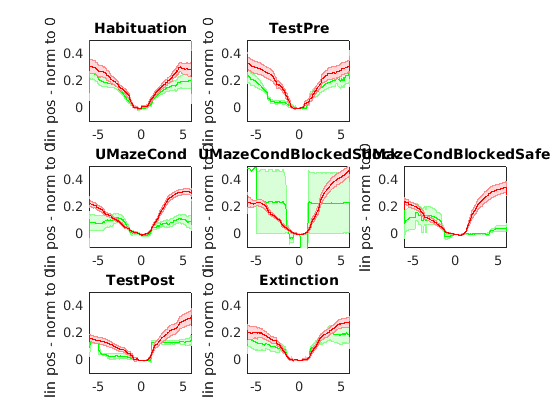


clear AssymAft AssymBef
Lim=-1;
figure
for ss=1:length(SessTypes)
    subplot(3,3,SessNum(ss))
    dattemp=-AllEventsPos.(SessTypes{ss}).ToSafe(AllEventsID.(SessTypes{ss}).ToSafe>Lim,:);
    for k=1:size(dattemp,1)
        dattemp(k,:)=(dattemp(k,:)-nanmean(dattemp(k,580:620)));
    end
    shadedErrorBar(tps-BefTime/1e4,nanmean((dattemp')'),stdError((dattemp')'),'g'); hold on
    dattemp=AllEventsPos.(SessTypes{ss}).ToShock(AllEventsID.(SessTypes{ss}).ToShock>Lim,:);
    for k=1:size(dattemp,1)
        dattemp(k,:)=(dattemp(k,:)-nanmean(dattemp(k,580:620)));
    end
    shadedErrorBar(tps-BefTime/1e4,nanmean((dattemp')'),stdError((dattemp')'),'r'); hold on
    AssymBef{ss}=max(dattemp(:,1:580)');
    AssymAft{ss}=max(dattemp(:,622:end)');
    ylabel('lin pos - norm to 0')
    title(SessTypes{ss})
    xlim([-BefTime/1e4 BefTime/1e4])
    ylim([-0.1 0.5])
end

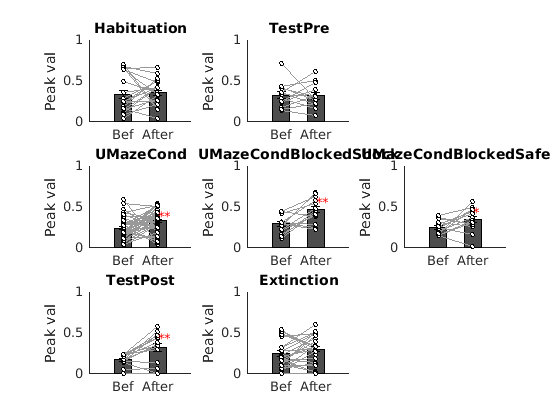

figure
for ss=1:length(SessTypes)
    subplot(3,3,SessNum(ss))
    PlotErrorBarN([AssymBef{ss};AssymAft{ss}]',0,1);
    title(SessTypes{ss})
    set(gca,'XTick',[1,2],'XTickLabel',{'Bef','After'})
    ylabel('Peak val')
end

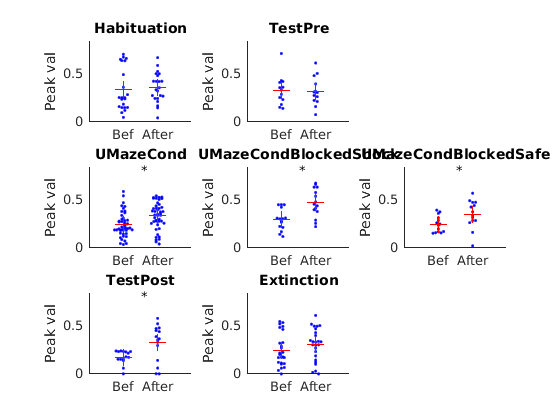

figure
for ss=1:length(SessTypes)
    subplot(3,3,SessNum(ss))
    plotSpread({AssymBef{ss},AssymAft{ss}},'showMM',2)
    [h,p]=ttest(AssymBef{ss},AssymAft{ss});
    if p<0.05
        text(1.5,0.8,'*')
    end
    title(SessTypes{ss})
    set(gca,'XTick',[1,2],'XTickLabel',{'Bef','After'})
    ylabel('Peak val')
    ylim([0 0.85])
end

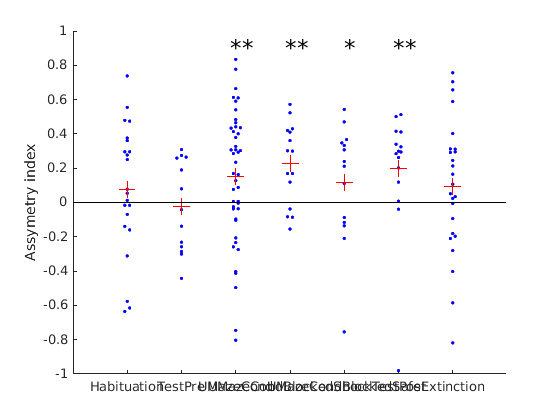


figure
for ss=1:length(SessTypes)
    A{ss}=(AssymAft{ss}-AssymBef{ss})./(AssymAft{ss}+AssymBef{ss});
    [h,p(ss)]=ttest(AssymBef{ss},AssymAft{ss});
end
plotSpread(A)
plotSpread(A,'showMM',2)
hold on
line(xlim,[0 0],'color','k')
for ss=1:length(SessTypes)
    if p(ss)<=0.01
        text(ss-0.1,0.9,'**','FontSize',18)
    elseif p(ss)<=0.05
        text(ss,0.9,'*','FontSize',18)
    end
end
set(gca,'XTick',[1:7],'XTickLabel',SessTypes)
ylabel('Assymetry index')

Look mouse by mouse

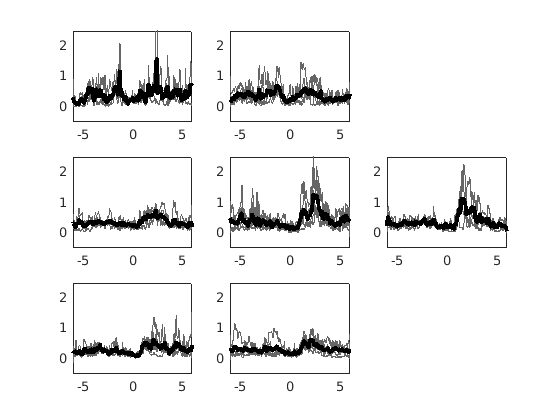

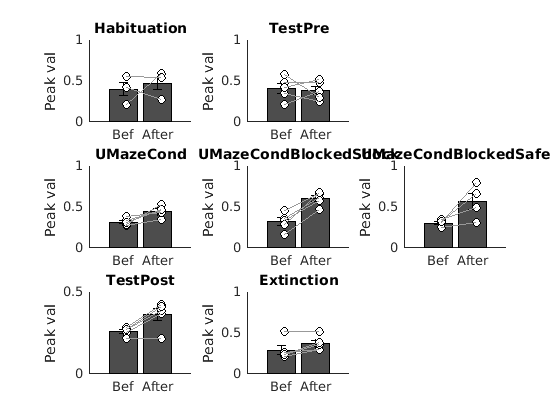

clear AssymAft AssymBef
BefPer=[200:580]; % to caclulate values before the turn
AftPer=[620:1001]; % to calculate values after the turn
NormPer=[580:620]; % to normalize to peak
figure
for ss=1:length(SessTypes)
    subplot(3,3,SessNum(ss))
    for mm=1:5
        if not(isempty(RiskAsess.(SessTypes{ss}).ToShockPos{mm}))
            MouseByMousePostion.(SessTypes{ss})(mm,:)=nanmean(RiskAsess.(SessTypes{ss}).ToShockMov{mm},1);
            MouseByMousePostion.(SessTypes{ss})(mm,:)=smooth(MouseByMousePostion.(SessTypes{ss})(mm,:),10);
            %             MouseByMousePostion.(SessTypes{ss})(mm,:)= MouseByMousePostion.(SessTypes{ss})(mm,:)-nanmean(MouseByMousePostion.(SessTypes{ss})(mm,NormPer));
            MouseByMouseAssymBef.(SessTypes{ss})(mm,:)=max(MouseByMousePostion.(SessTypes{ss})(mm,BefPer));
            MouseByMouseAssymAft.(SessTypes{ss})(mm,:)=max(MouseByMousePostion.(SessTypes{ss})(mm,AftPer));
            
        else
            MouseByMousePostion.(SessTypes{ss})(mm,:)=nan(1201,1);
            MouseByMouseAssymBef.(SessTypes{ss})(mm,:)=NaN;
            MouseByMouseAssymAft.(SessTypes{ss})(mm,:)=NaN;
            
        end
        
    end
    plot(tps-BefTime/1e4,MouseByMousePostion.(SessTypes{ss})','color',[0.4 0.4 0.4]), hold on
    plot(tps-BefTime/1e4,nanmean(MouseByMousePostion.(SessTypes{ss})),'color','k','linewidth',3), hold on
    xlim([-6 6])
    ylim([-0.5 2.5])
    title(SessTypes{ss})
    xlabel('time (s)')
    if SessNum(ss)==4
        ylabel('speed')
    end
end

figure
for ss=1:length(SessTypes)
    subplot(3,3,SessNum(ss))
    PlotErrorBarN_KJ([MouseByMouseAssymBef.(SessTypes{ss}),MouseByMouseAssymAft.(SessTypes{ss})],'newfig',0,'paired',1);
    title(SessTypes{ss})
    set(gca,'XTick',[1,2],'XTickLabel',{'Bef','After'})
    ylabel('Peak val')
end

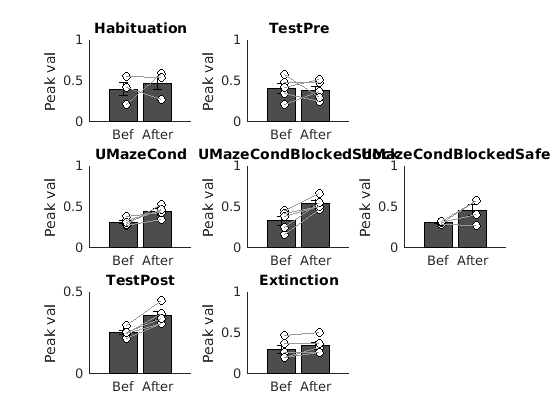

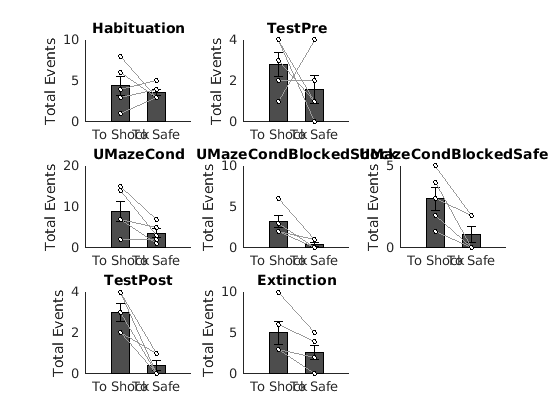

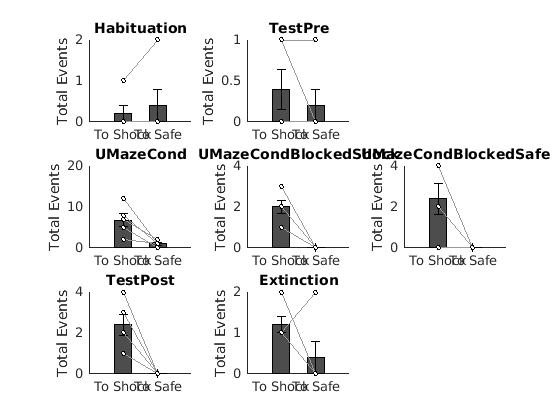

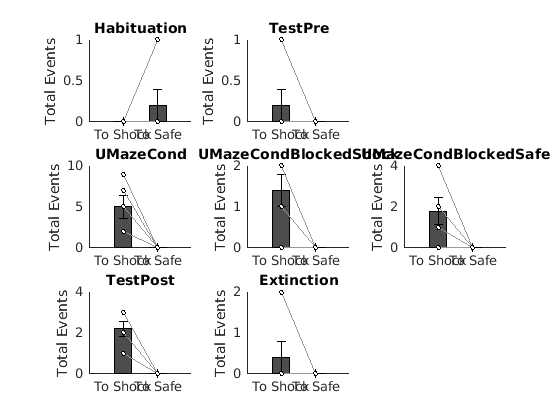

SessNum=[1,2,4,5,6,7,8];
for type=1:3
    figure
    DurSess=[400,180,480,180,180,180,900]/60;
    for ss=1:length(SessTypes)
        subplot(3,3,SessNum(ss))
        PlotErrorBarN([sum(RiskAsess.(SessTypes{ss}).ToShockNumEv{type}',1);sum(RiskAsess.(SessTypes{ss}).ToSafeNumEv{type}',1)]',0,1);
        set(gca,'XTick',[1,2],'XTickLabel',{'To Shock','To Safe'})
        ylabel('Total Events')
        title(SessTypes{ss})
    end
end

This only includes sessions that can be directly comapred with PAG protocol

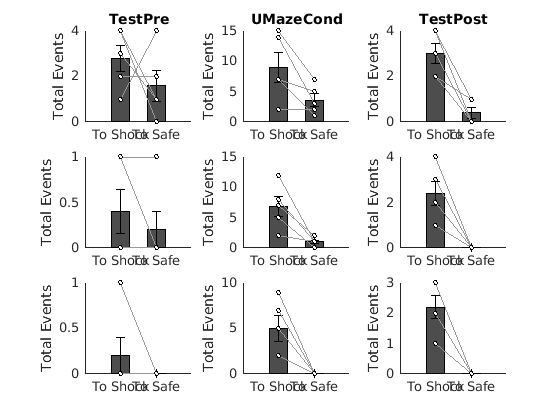

SessNum=[1,2,4,5,6,7,8];
figure
for type=1:3
    DurSess=[400,180,480,180,180,180,900]/60;
    ToUse=[2,3,6];
    for ss=1:length(ToUse)
        subplot(3,3,ss+(type-1)*3)
        PlotErrorBarN([sum(RiskAsess.(SessTypes{ToUse(ss)}).ToShockNumEv{type}',1);sum(RiskAsess.(SessTypes{ToUse(ss)}).ToSafeNumEv{type}',1)]',0,1);
        set(gca,'XTick',[1,2],'XTickLabel',{'To Shock','To Safe'})
        ylabel('Total Events')
        if type==1
            title(SessTypes{ToUse(ss)})
        end
        %ylim([0 6])
    end
end

SessNum=[1,2,3,5,6];
Lim=[0,2];
color={'m','k'};
figure
ss=3;
for ll=[1,2]
    shadedErrorBar(tps-BefTime/1e4,nanmean((AllEventsPos.(SessTypes{ss}).ToShock(AllEventsID.(SessTypes{ss}).ToShock==Lim(ll),:)')'),stdError((AllEventsPos.(SessTypes{ss}).ToShock(AllEventsID.(SessTypes{ss}).ToShock==Lim(ll),:)')'),color{ll}); hold on
    ylim([0 1.5])
    xlim([-BefTime/1e4 BefTime/1e4])
end